# Homework 4: RRR Robot

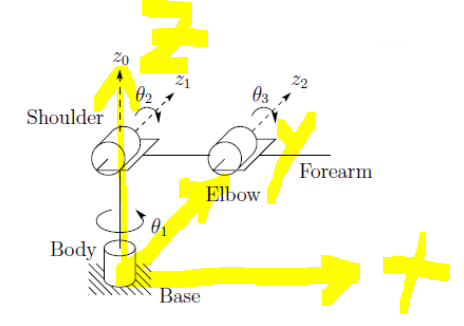

q1, q2, q3 are joint space variables

L1,L2,L3 are known

## Forward Kinematics


$$H=R_z \left(\mathrm{q1}\right)\cdot T_z \left(\mathrm{L1}\right)\cdot R_Y \left(\mathrm{q2}\right)\cdot T_x \left(\mathrm{L2}\right)\cdot R_Y \left(\mathrm{q3}\right)\ldotp T_x \left(\mathrm{L3}\right)$$



% set angles and links as symbolical
syms l1 l2 l3  q1 q2 q3  real
l1=1;
l2=1;
l3=1 ;
% forward kinematics
H = simplify(Rz(q1)*Tz(l1)*Ry(q2)*Tx(l2)*Ry(q3)*Tx(l3))

$$H = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & 1-\sin\left(q_{2}\right)-\sin\left(q_{2}+q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$

% extract rotation matrix
R = simplify(H(1:3,1:3))

$$R = \left(\begin{array}{ccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) \end{array}\right)$$

## task 1 

## Jacobian

### **Numerical derivatives**

% forward kinematics
H =Rz(q1)*Tz(l1)*Ry(q2)*Tx(l2)*Ry(q3)*Tx(l3);
H=simplify(H);
% extract rotation matrix
R = simplify(H(1:3,1:3));
% diff by q1
Td= Rzd(q1)*Tz(l1)*Ry(q2)*Tx(l2)*Ry(q3)*Tx(l3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 1st column
J1 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\sigma_{3}\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\sigma_{4}-\sigma_{2}\\ 0\\ 0\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{7}+\sigma_{6}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\left(\sigma_{1}-\sigma_{3}\right)}{\sigma_{7}+\sigma_{6}}\\ \frac{{\sin\left(q_{1}\right)}^{2}}{{\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}}+\frac{\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sigma_{4}-\sigma_{2}\right)}{\sigma_{5}}+\frac{\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{5}=\sigma_{7}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{7}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{6}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{6}\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{6}={\sin\left(q_{2}+q_{3}\right)}^{2}\\ \sigma_{7}={\cos\left(q_{2}+q_{3}\right)}^{2} \end{array}$$

% diff by q2
Td=Rz(q1)*Tz(l1)*Ryd(q2)*Tx(l2)*Ry(q3)*Tx(l3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 2nd column
J2 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J2 = \begin{array}{l} \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\sigma_{4}-\sigma_{3}\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-\sigma_{2}-\sigma_{1}\\ \sigma_{5}-\sigma_{6}-\cos\left(q_{2}\right)\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\sigma_{6}-\sigma_{5}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{7}}\\ \frac{\cos\left(q_{2}+q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)}{\sigma_{9}+\sigma_{8}}+\frac{\sin\left(q_{2}+q_{3}\right)\,\left(\sigma_{4}+\sigma_{3}\right)}{\sigma_{9}+\sigma_{8}}\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sigma_{2}+\sigma_{1}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)}{\sigma_{7}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}=\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{7}=\sigma_{9}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{9}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{8}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{8}\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{8}={\sin\left(q_{2}+q_{3}\right)}^{2}\\ \sigma_{9}={\cos\left(q_{2}+q_{3}\right)}^{2} \end{array}$$

% diff by q3
Td=Rz(q1)*Tz(l1)*Ry(q2)*Tx(l2)*Ryd(q3)*Tx(l3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 3rd column
J3 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J3 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{4}-\sigma_{3}\\ -\sigma_{2}-\sigma_{1}\\ \sigma_{5}-\sigma_{6}\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\sigma_{6}-\sigma_{5}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{7}}\\ \frac{\cos\left(q_{2}+q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)}{\sigma_{9}+\sigma_{8}}+\frac{\sin\left(q_{2}+q_{3}\right)\,\left(\sigma_{4}+\sigma_{3}\right)}{\sigma_{9}+\sigma_{8}}\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sigma_{2}+\sigma_{1}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)}{\sigma_{7}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}=\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{7}=\sigma_{9}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{9}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{8}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{8}\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{8}={\sin\left(q_{2}+q_{3}\right)}^{2}\\ \sigma_{9}={\cos\left(q_{2}+q_{3}\right)}^{2} \end{array}$$


% Full Jacobian 3x6
Jq = [simplify(J1), simplify(J2), simplify(J3)]

$$Jq = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}+q_{3}\right)-\cos\left(q_{2}\right) & -\cos\left(q_{2}+q_{3}\right)\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$